m = 1000

m = 1000

b = 50

b = 50

u = 500

u = 500

num = [1]

num = 1

den = [m b]

den =         1000          50


cruise = tf(num, den)

cruise =
 
       1
  -----------
  1000 s + 50
 
Continuous-time transfer function.
Model Properties


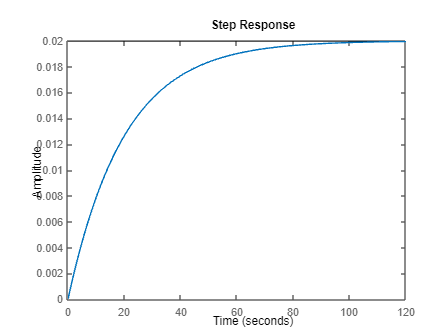

step(cruise)

m = 1000

m = 1000

b = 50

b = 50

u = 500

u = 500

A = [-b/m]

A = -0.0500

B = [1/m]

B = 1.0000e-03

C = [1]

C = 1

D = 0

D = 0

cruise = ss(A, B, C, D)

cruise =
 
  A = 
          x1
   x1  -0.05
 
  B = 
          u1
   x1  0.001
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


step(cruise)

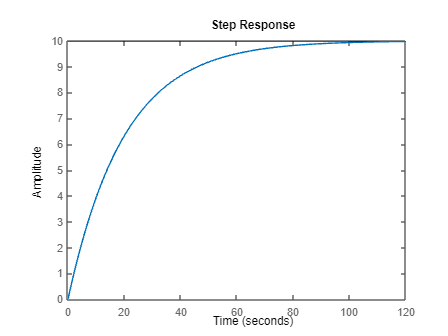

step(u*cruise)

J = 0.01

J = 0.0100

b = 0.1

b = 0.1000

K = 0.01

K = 0.0100

R = 1

R = 1

L = 0.5

L = 0.5000

num = K

num = 0.0100

den = [(J*L) ((J*R) + (L*b)) ((b*R)+K^2)]

den =     0.0050    0.0600    0.1001


cruise = tf(num, den)

cruise =
 
             0.01
  ---------------------------
  0.005 s^2 + 0.06 s + 0.1001
 
Continuous-time transfer function.
Model Properties


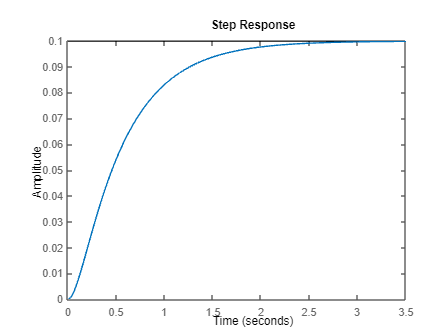

step(cruise)

%Experiment2 and 1 are combined

%P controller
M = 1

M = 1

b = 10

b = 10

K = 20

K = 20

num = 1

num = 1

den = [M b K]

den =      1    10    20


plant = tf(num, den)

plant =
 
         1
  ---------------
  s^2 + 10 s + 20
 
Continuous-time transfer function.
Model Properties


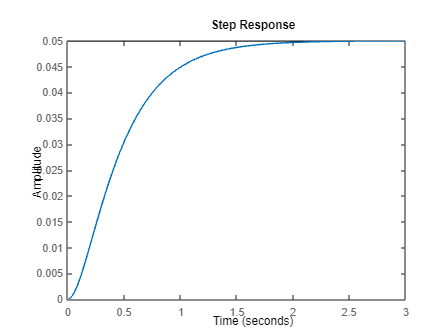

step(plant)


Kp = 300

Kp = 300

contr = Kp

contr = 300

sys_cl = feedback(contr*plant, 1)

sys_cl =
 
        300
  ----------------
  s^2 + 10 s + 320
 
Continuous-time transfer function.
Model Properties


t = 0:0.01:2

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


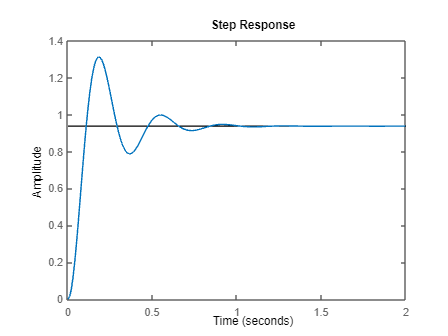

step (sys_cl,t)

%PD controller
M = 1

M = 1

b = 10

b = 10

K = 20

K = 20

num = 1

num = 1

den = [M b K]

den =      1    10    20


plant = tf(num, den)

plant =
 
         1
  ---------------
  s^2 + 10 s + 20
 
Continuous-time transfer function.
Model Properties



Kp = 300

Kp = 300

Kd = 1

Kd = 1

contr = tf([Kp Kd], 1)

contr =
 
  300 s + 1
 
Continuous-time transfer function.
Model Properties


sys_cl = feedback(contr*plant, 1)

sys_cl =
 
     300 s + 1
  ----------------
  s^2 + 310 s + 21
 
Continuous-time transfer function.
Model Properties


t = 0:0.01:2

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


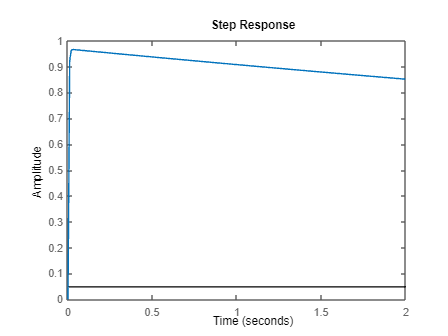

step (sys_cl,t)

%PI controller
M = 1

M = 1

b = 10

b = 10

K = 20

K = 20

num = 1

num = 1

den = [M b K]

den =      1    10    20


plant = tf(num, den)

plant =
 
         1
  ---------------
  s^2 + 10 s + 20
 
Continuous-time transfer function.
Model Properties



Kp = 300

Kp = 300

Ki = 70

Ki = 70

contr = tf([Kp Ki], [1 0])

contr =
 
  300 s + 70
  ----------
      s
 
Continuous-time transfer function.
Model Properties


sys_cl = feedback(contr*plant, 1)

sys_cl =
 
         300 s + 70
  -------------------------
  s^3 + 10 s^2 + 320 s + 70
 
Continuous-time transfer function.
Model Properties


t = 0:0.01:2

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


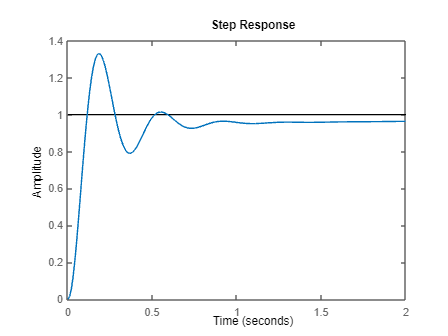

step (sys_cl,t)

%PID conrtroller
M = 1

M = 1

b = 10

b = 10

K = 20

K = 20

num = 1

num = 1

den = [M b K]

den =      1    10    20


plant = tf(num, den)

plant =
 
         1
  ---------------
  s^2 + 10 s + 20
 
Continuous-time transfer function.
Model Properties



Kp = 350

Kp = 350

Ki = 300

Ki = 300

Kd = 50

Kd = 50

contr = tf([Kd Kp Ki], [1 0])

contr =
 
  50 s^2 + 350 s + 300
  --------------------
           s
 
Continuous-time transfer function.
Model Properties


sys_cl = feedback(contr*plant, 1)

sys_cl =
 
     50 s^2 + 350 s + 300
  --------------------------
  s^3 + 60 s^2 + 370 s + 300
 
Continuous-time transfer function.
Model Properties


t = 0:0.01:2

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


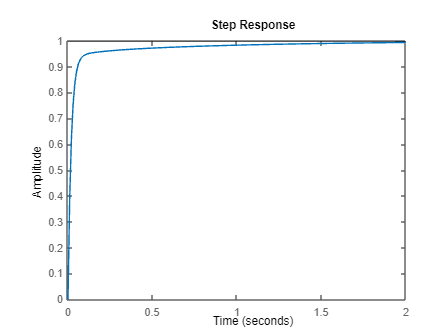

step (sys_cl,t)